# Creating and Training a CNN to Classify Traffic Signs

For the Week 1 Project, you will:

- Prepare the traffic signs dataset for training

- Create a simple CNN

- Train the model to classify traffic signs

- Evaluate your trained model on test data

After you have finished, please proceed to the **"Project: Classifying Traffic Signs with a Simple CNN" **assessment to answer questions about your results.

## Prepare Your Data for Training

Inside the "Traffic Signs" folder, the data is already separated into Train and Test folders. 

Create an image datastore from the training dataset named `imdsSigns`:

% Select the location of the training data set:
filename = "D:\Faraz\cv_matlab_cert\Deep Learning for Computer Vision\Data\Traffic Signs";
imdsSigns = imageDatastore(filename,"IncludeSubfolders",true,"LabelSource","foldernames")

imdsSigns =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\Traffic Signs\Test\End Speed Limit\sign00011221.png';
                              ' ...\Data\Traffic Signs\Test\End Speed Limit\sign00011223.png';
                              ' ...\Data\Traffic Signs\Test\End Speed Limit\sign00011224.png'
                               ... and 1185 more
                              }
                     Folders: {
                              ' ...\cv_matlab_cert\Deep Learning for Computer Vision\Data\Traffic Signs'
                              }
                      Labels: [End Speed Limit; End Speed Limit; End Speed Limit ... and 1185 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
    

% Count the number of images for each label
labelCounts = countEachLabel(imdsSigns);

% Get the number of unique labels (classes)
numClasses = height(labelCounts); % Or size(labelCounts, 1);

% Display the number of classes
fprintf('Number of classes in the datastore: %d\n', numClasses);

Number of classes in the datastore: 9



% Optional: Display the label counts for each class
disp('Label Counts:');

Label Counts:


disp(labelCounts);

         Label         Count
    _______________    _____

    End Speed Limit     132 
    Speed Limit 100     132 
    Speed Limit 120     132 
    Speed Limit 20      132 
    Speed Limit 30      132 
    Speed Limit 50      132 
    Speed Limit 60      132 
    Speed Limit 70      132 
    Speed Limit 80      132 



Use 80% of your data for training, leaving the remaining images for validation. Make sure to randomize which images are assigned to the validation set.

[imdsTrain,imdsValidation] = splitEachLabel(imdsSigns,0.8,"randomized");
% Using the length of the labels
numImagesTrain = length(imdsTrain.Labels);

% Display the number of images in the training set.
fprintf('Number of images in the training set: %d\n', numImagesTrain);

Number of images in the training set: 954



% Count the number of images for each label in the validation set.
validationLabelCounts = countEachLabel(imdsValidation);
% Display the counts for each class in the validation set.
disp('Number of images per class in the validation set:');

Number of images per class in the validation set:


disp(validationLabelCounts);

         Label         Count
    _______________    _____

    End Speed Limit     26  
    Speed Limit 100     26  
    Speed Limit 120     26  
    Speed Limit 20      26  
    Speed Limit 30      26  
    Speed Limit 50      26  
    Speed Limit 60      26  
    Speed Limit 70      26  
    Speed Limit 80      26  



% Define the mini-batch size.
miniBatchSize = 128;

% Calculate the number of mini-batches.
numMiniBatches = ceil(numImagesTrain / miniBatchSize);

% Display the number of mini-batches.
fprintf('Number of mini-batches: %d\n', numMiniBatches);

Number of mini-batches: 8


## Preview the Training Data

Before you dive into building your network architecture, it's worth familiarizing yourself with the images in this data set. 

Run this section several times to preview some of the training data:

img = read(imdsSigns);
size(img)

ans =     37    36     3


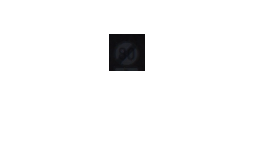

imshow(img)

Notice how many of the images are small, dark, blury, or otherwise difficult to see. 

All images are in RGB format, with sizes  $m \times n \times 3$, but they have a range of different sizes. Before you can train, you will have to resize these images to match the image input layer.

## Define the Network Architecture

The following code will open the Deep Network Designer App. Use the app to create and export a network with the following layers:

- `imageInputLayer`

- `convolution2dLayer`

- `reluLayer`

- `maxPooling2dLayer`

- `fullyConnectedLayer`

- `softmaxLayer`

- `classificationLayer`

Make sure you specify the correct `OutputSize` for `fullyConnectedLayer`.

if isMATLABReleaseOlderThan("R2024a")
    deepNetworkDesigner
else
    deepNetworkDesigner -v1
end

% Insert the code generated from the Deep Network Designer App:

layers = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    fullyConnectedLayer(9,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Resize Your Training Data

Resize the training and validation data to match the `InputSize` that you set above:

augTrain = augmentedImageDatastore([227,227],imdsTrain);
augVal = augmentedImageDatastore([227,227],imdsValidation);

## Setting the Training Options

Finally, set your training options. You'll investigate training options in more detail later in this course. For now, use the same options as you saw in the video:

- Set the solver to `"adam"`

- Include the validation data you set aside earlier

- Set the Shuffle option to `"every-epoch"`

- Set the Plots option to `"training-progress"`

% Insert code to set the training options:
opts = trainingOptions("adam","ValidationData",augVal,"Shuffle",...
    "every-epoch","Plots","training-progress");

## Train the Network

It's finally time to train your network! 

% Insert code to train your network:
net = trainNetwork(augTrain,layers,opts);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:54 |       18.75% |       12.39% |      30.7497 |   14183.6475 |          0.0010 |


Training will likely take about 20 minutes using a CPU.

## Performance on Test Data

Once you have trained your network, you should examine its performance on your test data.

Don't forget to resize your images to match the expected input size for your trained network:

filenameTest = "D:\Faraz\cv_matlab_cert\Deep Learning for Computer Vision\Data\Traffic Signs\Test";



Finally, use your test data to evaluate your trained network, including calculating the test accuracy and creating a confusion chart. You may need to click the arrow and open your confusion charts in the figure window to see them well:

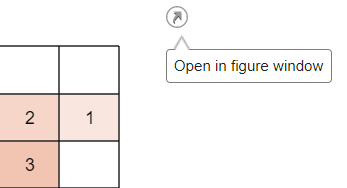

% Classify your test data:
imdsTest = imageDatastore(filenameTest,"IncludeSubfolders",true,"LabelSource","foldernames");

augTest = augmentedImageDatastore([227,227],imdsTest);
testPreds = classify(net,augTest);

testAccuracy = nnz(testPreds == imdsTest.Labels)/length(testPreds)

% Compute the test accuracy and create a confusion chart:
confusionchart(imdsTest.Labels,testPreds)


While not perfect, this network performs surprisingly well considering the limited data set and the relatively simple architecture of your neural network. Later in this course, you will see how to achieve much better accuracy and loss values for this dataset.

Once you have completed this reading, proceed to the "Week 1 Project: Classifying Traffic Signs with a Simple CNN" quiz. You may want to keep this completed live script open as a reference as you answer questions about your results.

*Copyright 2024 The MathWorks, Inc.*